# Exercise 3

Use optimization techniques to perform pattern synthesis to enable beamforming, nulling and steering while meeting requirements for array performance.

Mathematically, calculating beamforming weights is an optimization problem. For example, the popular minimum variance beamformer is used to minimize the total noise output while preserving the signal from a given direction. 

**Steps:**

Create a Uniform Linear Array (ULA) to meet given requirements for array performance:

- Review given requirements

- Create a ULA

- Use the minimum variance optimization algorithm

- Meet the requirements for array performance

## Create a Uniform Linear Array (ULA) and view the beam pattern

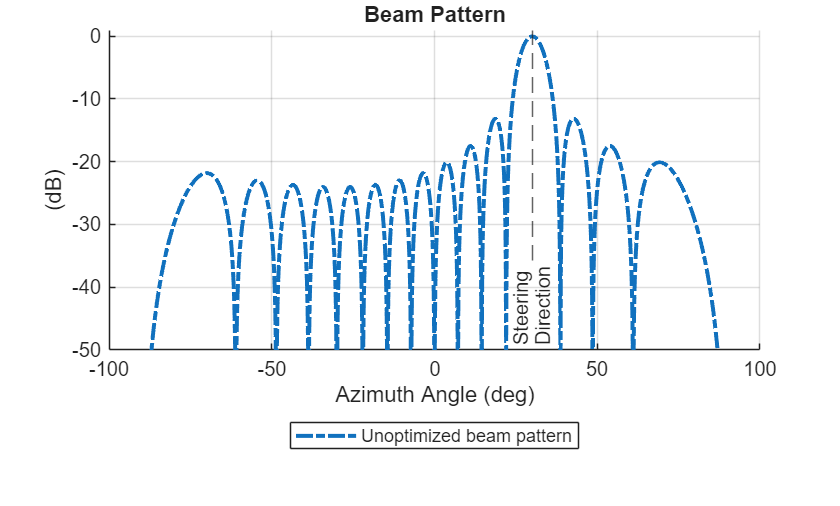

% ADD CODE HERE
% Define the operating frequency (fc) and calculate the wavelength (lamda)
% We need element spacing of lamda/2 to avoid grating lobes and minimize
% mutual coupling between elements
fc = ;
lambda = freq2wavelen(fc);

% ADD CODE HERE
% Define the number of elements in the ULA (N)
N = ;

% ADD CODE HERE
% Create a ULA. Type 'doc phased.ULA' for more information.
% The ULA has "N" elements and half a wavelength "lamda" spacing
% Output the ULA object into a variable "array"
array = ;

% ADD CODE HERE
% Define the required steering angle  (steeringAngle)
steeringAngle = ;

% The fuction 'steervec' is used to calculate the response of the array and 'pattern' is
% used to view the resultant beam pattern.
elementPositions = getElementPosition(array)/lambda; 
steeringWeights = steervec(elementPositions, steeringAngle);
azimuthGrid = -90:0.1:90;
unoptimizedPattern = pattern(array, fc, azimuthGrid, 0,...
    Type='powerdb', CoordinateSystem='rectangular', Weights=steeringWeights);

helperPlotBeamPattern(azimuthGrid, unoptimizedPattern, steeringAngle);

## Define Side Lobe Levels and Null Locations

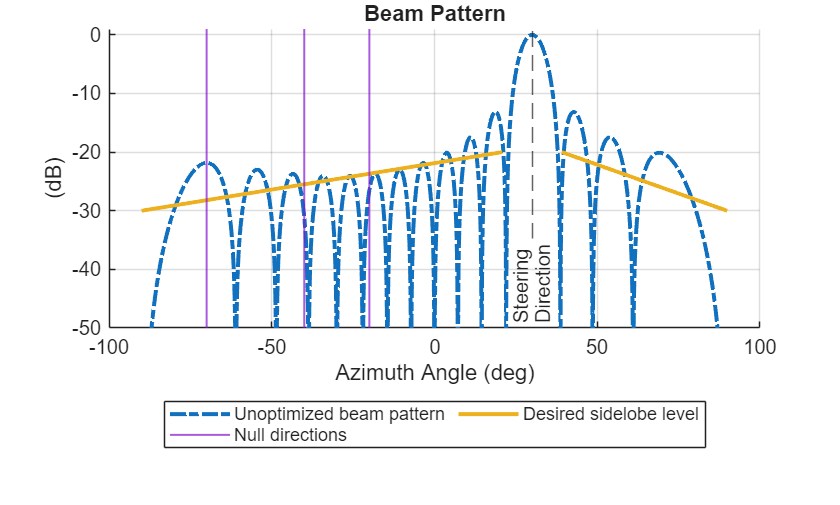

% The following lines of code calculate the gap in the mask to account for
% the main lobe.

% Null-to-null beamwidth. Divide by cosine to account for beam broadening
% due to steering off broadside
nnBeamWidth = array.beamwidth(fc, "dBDown", Inf)/cosd(steeringAngle);

% Leave more room for the main lobe. As the sidelobes are suppressed the main lobe width will increase
a = 1.1;

% ADD CODE HERE
% Define the min and max levels for the sidelobe mask. We are implementing
% a symmetric mask but you could provide custom mask levels.
maxSidelobe = ;
minSidelobe = ;

% Vector pair of angles and values for both sidelobe directions. 
% Angles from +/-90 to main beam. 
% Values decrease linearly from max to min.
leftSidelobeAngles = -90:0.2:(steeringAngle - a*nnBeamWidth/2);
leftSidelobeValues = linspace(minSidelobe, maxSidelobe, numel(leftSidelobeAngles));

rightSidelobeAngles = (steeringAngle + a*nnBeamWidth/2):0.2:90;
rightSidelobeValues = linspace(maxSidelobe, minSidelobe, numel(rightSidelobeAngles));

% ADD CODE HERE
% Define required null angles in a vector
nullDirections = [];

% View the requirement mask on top of unoptimized pattern
helperPlotBeamPattern(azimuthGrid, unoptimizedPattern, steeringAngle, ...
    LeftSidelobeAngles=leftSidelobeAngles, LeftSidelobeValues=leftSidelobeValues,...
    RightSidelobeAngles=rightSidelobeAngles, RightSidelobeValues=rightSidelobeValues, ...
    NullDirections=nullDirections);

## Use the minimum-variance array pattern synthesis algorithm

maskAngles = [leftSidelobeAngles rightSidelobeAngles];
maskAngles = [maskAngles; zeros(size(maskAngles))];
maskValues = [leftSidelobeValues rightSidelobeValues];

% ADD CODE HERE
% Use the 'minvarweights' function to calculate array weights
% Type >> 'doc minvarweights' into the command line for more information
% Use the calculated element positions, desired steering angle as inputs
% Enter as Name-Value pairs the 'MaskAngle', 'MaskSidelobeLevel' and 'NullAngle'
% Store the output in variable 'optimizedWeights'

optimizedWeights = ;


## Plot and view the resultant patterns with mask overlay

optimizedPattern = pattern(array, fc, azimuthGrid, 0,...
    Type='powerdb', CoordinateSystem='rectangular', Weights=optimizedWeights);

% View the UNOPTIMIZED pattern with the mask overlay
helperPlotBeamPattern(azimuthGrid, unoptimizedPattern, steeringAngle, ...
    LeftSidelobeAngles=leftSidelobeAngles, LeftSidelobeValues=leftSidelobeValues,...
    RightSidelobeAngles=rightSidelobeAngles, RightSidelobeValues=rightSidelobeValues, ...
    NullDirections=nullDirections);

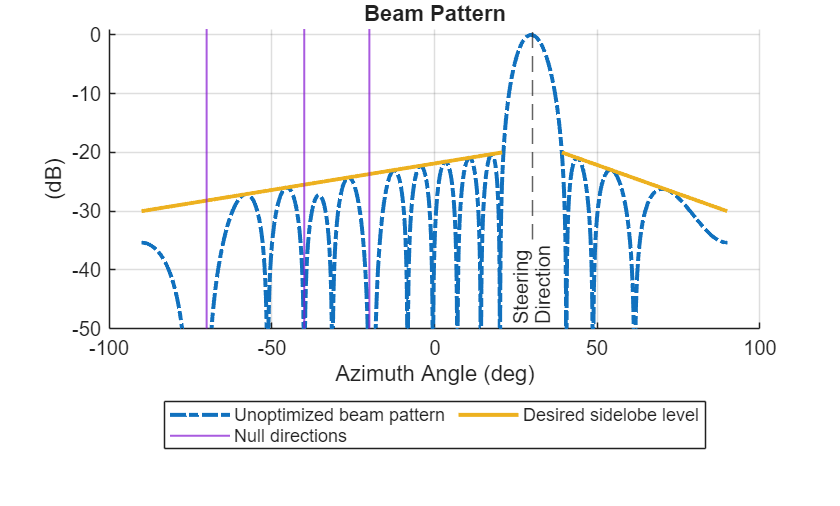


% View the OPTIMIZED pattern with the mask overlay
helperPlotBeamPattern(azimuthGrid, optimizedPattern, steeringAngle, ...
    LeftSidelobeAngles=leftSidelobeAngles, LeftSidelobeValues=leftSidelobeValues,...
    RightSidelobeAngles=rightSidelobeAngles, RightSidelobeValues=rightSidelobeValues, ...
    NullDirections=nullDirections)